## `STRING ALIGNMENT USING SAME CONSTRAINTS AS RNA-FOLDING`

`On using the same set of constraints as mentioned above, by excluding the addition constraint and the change made in the objective function, the entire formulation with a small change can be used to perform string alignment also. In string alignment we try to aling two strings of same length in such a way that maximum number of characters in them match. This is mainly used to check for evolutionary pattern in various sequences. The small change which is to be made is that, in earlier case we paired a nucleotid with it's complement, but in this case we are supposed pair the nucleotide with same other nucleotide in the sequence i.e., in constraint-1 instead of comparing two nucleotides if they are complement of each other, here we must check if they both are same as each other. The remaining part of the formulation remains to be exactly the same as previous one i.e., each nucleotide must be paired only to one other nucleotide and nested pairing or not possible. The objective function also remains the same that, the number of pairings must be maximized.`

clc;
clear all;
close all;
warning('off','all');

str1 = "UGCAGCU";
str2 = "UGCAGAU";
seq = convertStringsToChars(str1+reverse(str2));
n= length(seq);
rna_fold = optimproblem('ObjectiveSense','maximize');
vars = optimvar("vars",[n,n],"LowerBound",0,"Type","integer","UpperBound",1);

### `OBJECTIVE FUNCTION`

sum = optimexpr;
for i=1:n
    for j=i:n
        sum = sum + vars(i,j);
    end
end
rna_fold.Objective = sum;

### `REMOVING REDUNDANCY`

list1 = [];
for i=1:n
    for j=1:n
        if i>=j
            eqn = vars(i,j)==0;
            list1 = [list1;eqn];
        end
    end
end
rna_fold.Constraints.neccesary = list1;

### `CONSTRAINT - 1`

eqnns1 = [];
for i=1:n
    for j=1:n
        if i<j
            if seq(i)~=seq(j)
                eqn = vars(i,j) == 0;
                eqnns1 = [eqnns1;eqn];
            end 
        end
    end
end
rna_fold.Constraints.set1 = eqnns1;

### `CONSTRAINT - 2`

eqnns2 = [];
for i=1:n
    eqn = optimexpr;
    for j=1:n
        if i~=j
            if i<j
                eqn = eqn+vars(i,j);
            elseif i>j
                eqn = eqn+vars(j,i);
            end
        end
    end
    eqns = eqn<=1;
    eqnns2 = [eqnns2;eqns];
end
rna_fold.Constraints.set2 = eqnns2;

### `CONSTRAINT - 3`

nums = nchoosek([1:length(seq)],4);
eqnns3 = [];
b = size(nums);
for i=progress(1:b(1))
    eqn = vars(nums(i,1),nums(i,3))+vars(nums(i,2),nums(i,4))<=1;
    eqnns3 = [eqnns3;eqn];
end

Processing:  000%  |                                    | 0/1001it [00:00:00<Inf:NaN:NaN, Inf it/s]


rna_fold.Constraints.set3 = eqnns3;

[sol,fval] = solve(rna_fold);

Solving problem using intlinprog.
LP:                Optimal objective value is -7.000000.                                            

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -3.000000.                                                        
                   Relative gap is 75.00%.                                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -4.000000.                                                        
                   Relative gap is 40.00%.                                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -5.000000.                                                        
                   Relative gap is 16.67%.              

begin = [];
end1 = [];
for i=1:n
    for j=1:n
        if sol.vars(i,j)==1
            begin = [begin,i];
            end1 = [end1,j];
        end
    end
end
begin,end1

begin =      1     2     3     4     5     7


end1 =     14    13    12    11    10     8


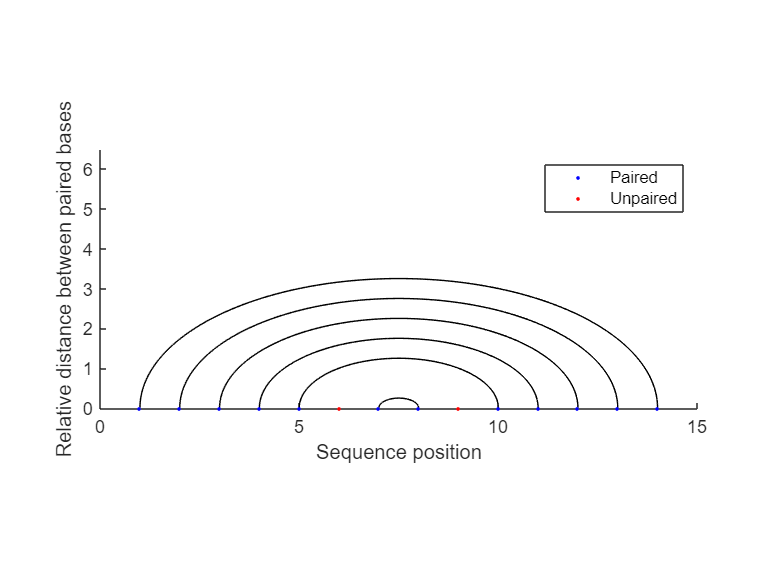

dot_bracket = '';
for i=1:length(seq)
    if ismember(i,begin)
        dot_bracket = [dot_bracket,'('];
    elseif ismember(i,end1)
        dot_bracket = [dot_bracket,')'];
    else
        dot_bracket = [dot_bracket,'.'];
    end
end
rnaplot(dot_bracket,'Format','Graph')